**Find the distancce between **

- **the centers of the pure yellow (255,255,0) and pure cyan (0,255,255) circles...**

- **the closest points of the pure magenta (255,0,255) and medium  grey (128, 128, 128) squares**

- **the magenta square will always be above and to the right of the gray square**

- **length of white rectangle represents one mile in pixels**

- **all answers need to be converted to miles**

Read image

img = imread('distances.png');


Show image

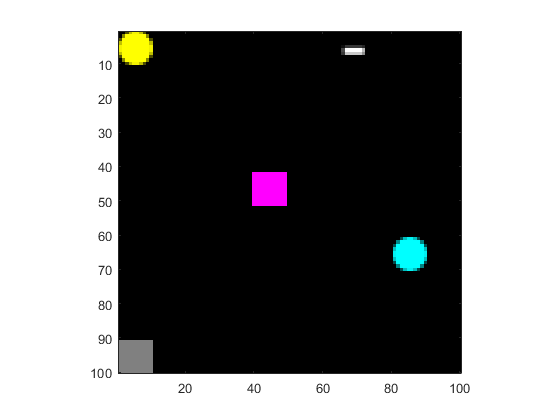

image(img)
axis tight; axis equal;

**Calculate Scale from white Rectangle**

Create masks to indicate the pure white pixels in the image

whiteMask = img(:,:,1)==255 & img(:,:,2)==255 & img(:,:,3)==255;

Find the coordinates (rows,cols) of the located pixels

[whiteRows, whiteCols] = find(whiteMask);


Calculate width of white rectangle

max(whiteCols)

ans = 71

min(whiteCols)

ans = 67

pixPerMile = max(whiteCols)-min(whiteCols)+1

pixPerMile = 5

**Distance between the Center of the Circles**

Create masks to indicate the pure yellow and pure cyan pixels in the image

yellowMask = img(:,:,1)==255 & img(:,:,2)==255 & img(:,:,3)==0;
cyanMask = img(:,:,1)==0 & img(:,:,2)==255 & img(:,:,3)==255;


Find the coordinates (rows,cols) of the located pixels

[yellowRows, yellowCols] = find(yellowMask);
[cyanRows, cyanCols] = find(cyanMask);

Locate a corner and determine radii so that you can calculate center location of each circle

yellowTopLeft = [min(yellowRows), min(yellowCols)]

yellowTopLeft =      2     2


cyanTopLeft = [min(cyanRows), min(cyanCols)]

cyanTopLeft =     62    82



yellowRadius = (max(yellowRows)-min(yellowRows)+1)/2

yellowRadius = 4

cyanRadius = (max(cyanRows)-min(cyanRows)+1)/2

cyanRadius = 4


yellowCenter = [yellowTopLeft(1)+yellowRadius, yellowTopLeft(2)+yellowRadius]

yellowCenter =      6     6


cyanCenter = [cyanTopLeft(1)+cyanRadius, cyanTopLeft(2)+cyanRadius]

cyanCenter =     66    86


Calculate distance

distanceInPix = sqrt( (yellowCenter(1)-cyanCenter(1))^2 + (yellowCenter(2)-cyanCenter(2))^2 )

distanceInPix = 100

distanceInMiles = distanceInPix/pixPerMile

distanceInMiles = 20

**Distance between the points of the Squares**

Create masks to indicate the pure yellow and pure cyan pixels in the image

magentaMask = img(:,:,1)==255 & img(:,:,2)==0 & img(:,:,3)==255;
grayMask = img(:,:,1)==128 & img(:,:,2)==128 & img(:,:,3)==128;


Find the coordinates (rows,cols) of the located pixels

[magentaRows, magentaCols] = find(magentaMask);
[grayRows, grayCols] = find(grayMask);

Locate a corners

magentaBottomLeft = [max(magentaRows), min(magentaCols)]

magentaBottomLeft =     51    40


grayTopRight = [min(grayRows), max(grayCols)]

grayTopRight =     91    10


Calculate distance

distanceInPix = sqrt( (magentaBottomLeft(1)-grayTopRight(1))^2 + (magentaBottomLeft(2)-grayTopRight(2))^2 )

distanceInPix = 50

distanceInMiles = distanceInPix/pixPerMile

distanceInMiles = 10